**Exercise 001**

Generate M3 and M5 using a loop structure

M3 = ones(10,10);
disp(M3)

     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1




M5 = eye(5,5);
disp(M5)

     1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1





M3_new = zeros(10, 10);
for ii=1:numel(M3_new)
    M3_new(ii) = 1;
end
disp(M3_new)

     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1




M5_new = zeros(5,5);
for ii=1:5
    M5_new(ii,ii) = 1;    
end
disp(M5_new)

     1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



#### Exercise 002

Write a code to generate the following matrix

    0     1     0     0     0     0

    0     0     1     0     0     0

    0     0     0     1     0     0

    0     0     0     0     1     0

    0     0     0     0     0     1

    0     0     0     0     0     0

e2 = diag(ones(1,5), 1);
e2

e2 =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0



e3 = zeros(6, 6);
for ii=1:5
    e3(ii, ii+1) = 1;    
end

e3

e3 =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0


#### Exercise 003

Write a code to generate M1~M9

(a) You can use for-loop(s) if needed.

(b) You only use the functions above (Do not use a loop structure).

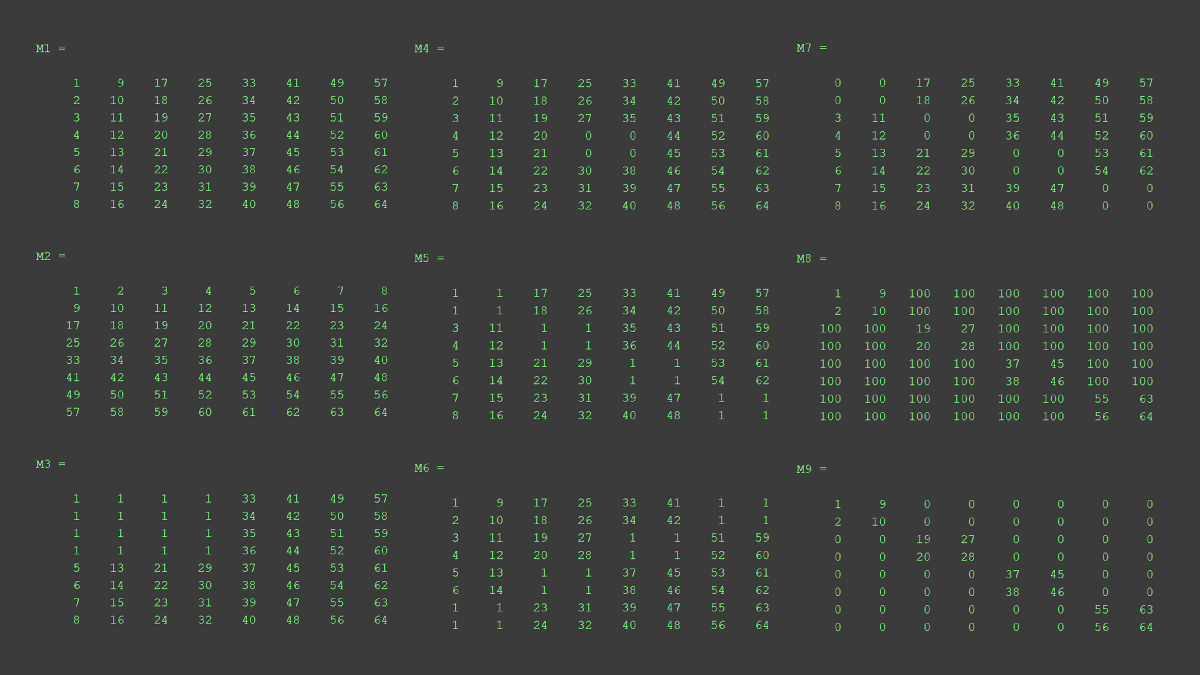

M1 = reshape(1:64, 8, 8)

M1 =      1     9    17    25    33    41    49    57
     2    10    18    26    34    42    50    58
     3    11    19    27    35    43    51    59
     4    12    20    28    36    44    52    60
     5    13    21    29    37    45    53    61
     6    14    22    30    38    46    54    62
     7    15    23    31    39    47    55    63
     8    16    24    32    40    48    56    64



M2 = M1';

M3 = M1;
M3(1:4, 1:4) = 1

M3 =      1     1     1     1    33    41    49    57
     1     1     1     1    34    42    50    58
     1     1     1     1    35    43    51    59
     1     1     1     1    36    44    52    60
     5    13    21    29    37    45    53    61
     6    14    22    30    38    46    54    62
     7    15    23    31    39    47    55    63
     8    16    24    32    40    48    56    64



M4 = M1;
M4(4:5, 4:5) = 0

M4 =      1     9    17    25    33    41    49    57
     2    10    18    26    34    42    50    58
     3    11    19    27    35    43    51    59
     4    12    20     0     0    44    52    60
     5    13    21     0     0    45    53    61
     6    14    22    30    38    46    54    62
     7    15    23    31    39    47    55    63
     8    16    24    32    40    48    56    64



A = ones(2,2);
mask = blkdiag(A,A,A,A)

mask =      1     1     0     0     0     0     0     0
     1     1     0     0     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     1     1



A = repelem(eye(2), 2, 2);
B = zeros(4, 4);

mask = [A,B;B A]

mask =      1     1     0     0     0     0     0     0
     1     1     0     0     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     1     1     0     0     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     1     1



M5 = mask + M1.*~mask

M5 =      1     1    17    25    33    41    49    57
     1     1    18    26    34    42    50    58
     3    11     1     1    35    43    51    59
     4    12     1     1    36    44    52    60
     5    13    21    29     1     1    53    61
     6    14    22    30     1     1    54    62
     7    15    23    31    39    47     1     1
     8    16    24    32    40    48     1     1


M6 = fliplr(mask) + M1.*~fliplr(mask)

M6 =      1     9    17    25    33    41     1     1
     2    10    18    26    34    42     1     1
     3    11    19    27     1     1    51    59
     4    12    20    28     1     1    52    60
     5    13     1     1    37    45    53    61
     6    14     1     1    38    46    54    62
     1     1    23    31    39    47    55    63
     1     1    24    32    40    48    56    64



M7 = M1;
M7(logical(mask)) = 0

M7 =      0     0    17    25    33    41    49    57
     0     0    18    26    34    42    50    58
     3    11     0     0    35    43    51    59
     4    12     0     0    36    44    52    60
     5    13    21    29     0     0    53    61
     6    14    22    30     0     0    54    62
     7    15    23    31    39    47     0     0
     8    16    24    32    40    48     0     0



M8 = M1;
M8(~logical(mask)) = 100

M8 =      1     9   100   100   100   100   100   100
     2    10   100   100   100   100   100   100
   100   100    19    27   100   100   100   100
   100   100    20    28   100   100   100   100
   100   100   100   100    37    45   100   100
   100   100   100   100    38    46   100   100
   100   100   100   100   100   100    55    63
   100   100   100   100   100   100    56    64



M9 = M1 .* mask

M9 =      1     9     0     0     0     0     0     0
     2    10     0     0     0     0     0     0
     0     0    19    27     0     0     0     0
     0     0    20    28     0     0     0     0
     0     0     0     0    37    45     0     0
     0     0     0     0    38    46     0     0
     0     0     0     0     0     0    55    63
     0     0     0     0     0     0    56    64


#### Exercise 004

- Read a 'coloredChips.png' image (run imread('coloredChips.png'))

- Find a location(s) of a RGB pixel in the image that has a value ranging from [150 0 0] to [255 100 100]. This means the ranges of R, G, and B are (150 255), (0 100), (0 100), respectively. 

- Make a new img where the pixels that do not satisfy the above conditions set to zeros.

- Show the new img

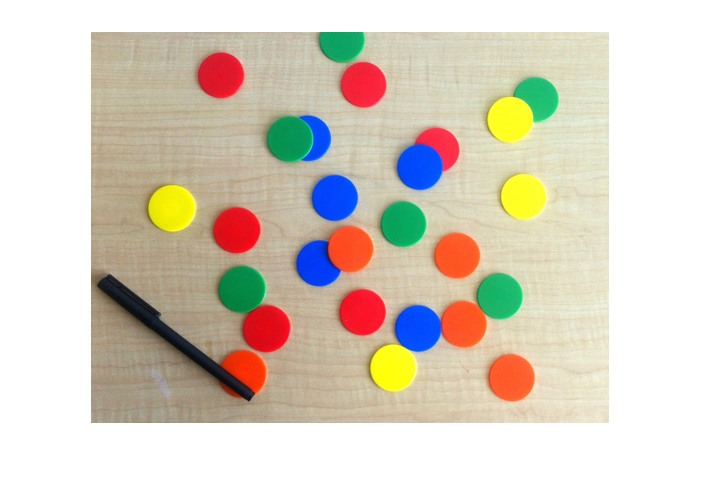

img = imread('coloredChips.png');
imshow(img)

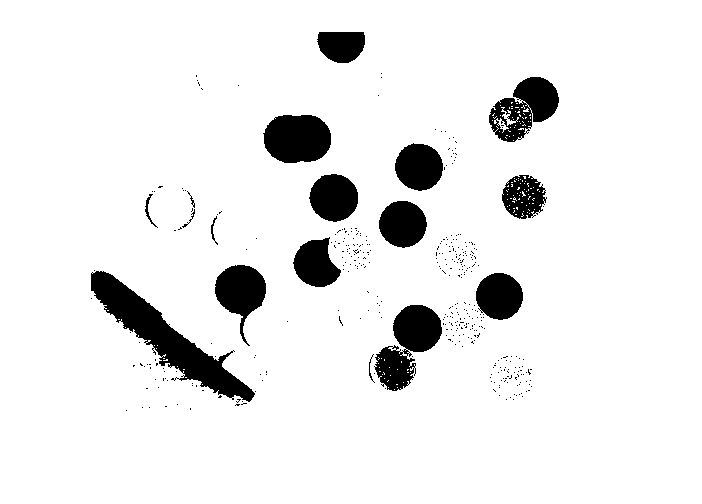


mask = zeros(size(img));
mask(:,:,1) = and(img(:,:,1) > 150, img(:,:,1) < 255);

imshow(mask(:,:,1))

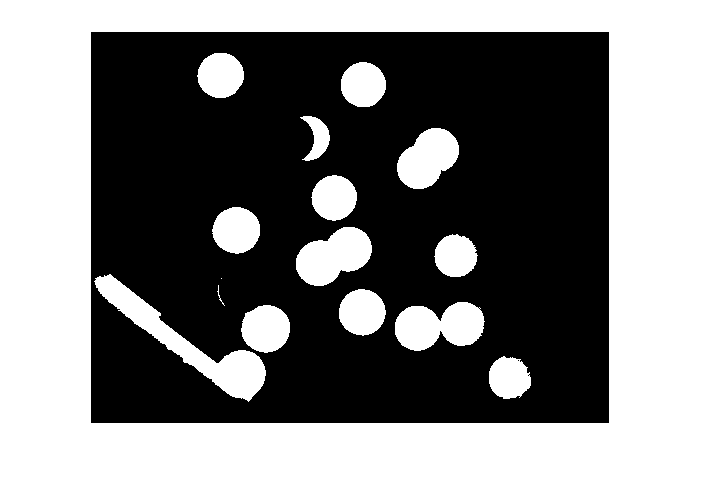


mask(:,:,2) = and(img(:,:,2) > 0, img(:,:,2) < 100);
imshow(mask(:,:,2))

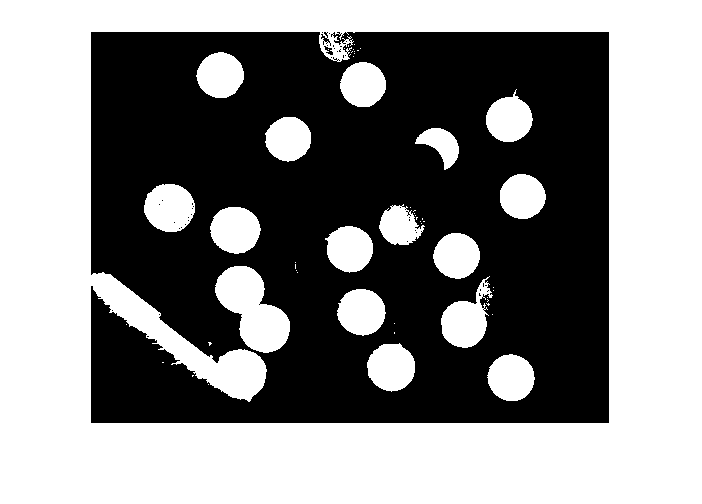


mask(:,:,3) = and(img(:,:,3) > 0, img(:,:,3) < 100);

imshow(mask(:,:,3))

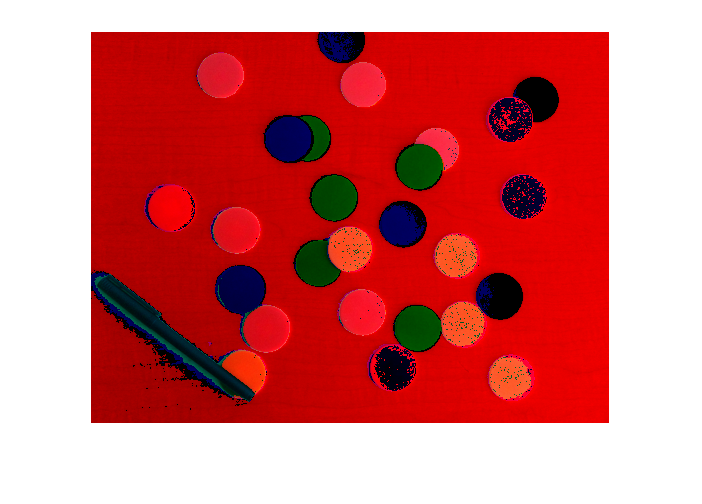


img(~mask) = 0;

imshow(img)